## **相関係数**

ここではある身長のデータと体重のデータの間に関係があるのかどうかを調べるため，**相関係数**を求めましょう．

% 10人分の身長データ(単位cm)
a = [152 146 148 155 149 150 147 158 161 144]

a =    152   146   148   155   149   150   147   158   161   144


% 10人分の体重データ(単位kg)
b = [48 40 46 45 44 44 42 50 52 38]

b =     48    40    46    45    44    44    42    50    52    38


2種類のデータにおいて，片方のデータの変化がもう片方のデータの変化に影響を及ぼすような関係を相関関係といいます．相関関係を調べるためには相関係数を求めることで、どのような影響を及ぼしているかを数値として表すことができます．相関係数の式は二つのデータを x と y としたとき，x と y それぞれの標準偏差$s_x$，$s_y$と以下の式で計算される x と y の共分散$s_{\textrm{xy}}$が必要です．


$$s_{\textrm{xy}} =\frac{1}{n}\left\lbrace \left(x_1 -\bar{x} \right)\left(y_1 -\bar{y} \right)+\left(x_2 -\bar{x} \right)\left(y_2 -\bar{y} \right)+\cdots +\left(x_n -\bar{x} \right)\left(y_n -\bar{y} \right)\right\rbrace$$


相関係数はこれらより以下のように計算される-1から1の間の数字です．


$$r_{\textrm{xy}} =\frac{s_{\textrm{xy}} }{s_x s_y }$$


1に近ければ正の相関があり，-1に近ければ負の相関があり，0に近ければ無相関であるといいます．正の相関とは，片方のデータが増加するともう片方のデータも増加するといった同じ傾向を表す関係です．一方，負の相関とは，片方のデータが増加するともう片方のデータは減少するといった逆の傾向を表す関係です．

それでは MATLAB® で計算してみましょう．

correlation = corr2(a, b) % 身長と体重データの相関係数を求める

correlation = 0.9085

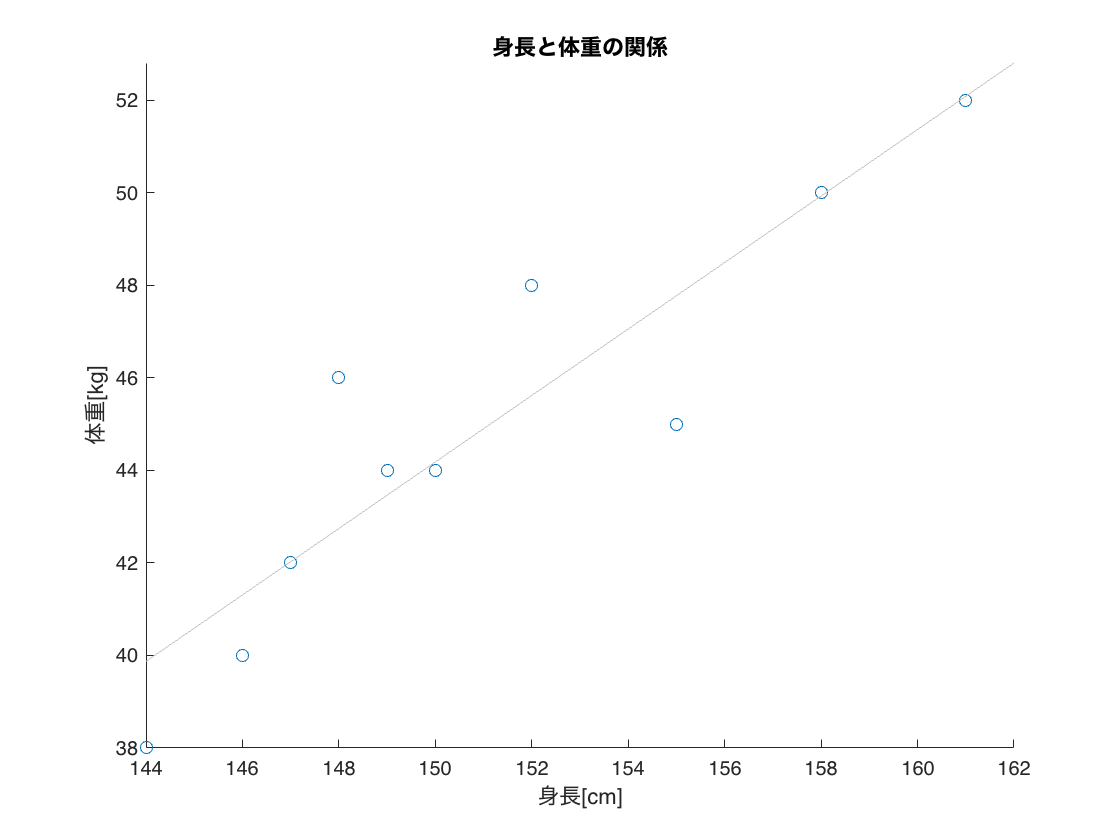

figure % 新しいウィンドウを用意
scatter(a, b) % 散布図を作る
xlabel('身長[cm]') % 横軸のラベル
ylabel('体重[kg]') % 縦軸のラベル
title('身長と体重の関係') % タイトルをつける
lsline % 近似直線を引く

相関係数は1に近い値となり，また散布図でも右肩上がりの正の傾きを持つ直線の周りにデータが集まっているように見えます．身長と体重の間には大きな正の相関関係があると言えますね．

実際の分析で相関係数を利用するときに注意してほしいのが，相関関係と因果関係は違うということです．直接関係なさそうなデータで相関係数が大きくなってもただの偶然かもしれません．計算して終わりではなく，しっかり理由まで考察する必要があるのです．

参考：[`corr2`](matlab:doc('corr2'))，[`scatter`](matlab:doc('scatter'))，[`lsline`](matlab:doc('lsline'))

[Mission3に戻る](matlab:closeAndMove("sbda_mission3.mlx"))

Copyright 2020 - 2022 The MathWorks, Inc.